# Random Numbers

## Why Random Numbers

Generating a series of random numbers is important for 

- Cryptography

- Statistical sampling (statistic mechanics, anyone?)

- Signal analysis

- Monte Carlo simulations

- Monte Carlo integrations

- Game design *(No Man’s Sky, Minecraft, Civilization)*

## Random Number Generators and Seeds

- Every random number generator actually generates ***pseudorandom ***numbers and thus needs a “starting point” – *a seed*

- The most *basic* generator is the *Linear Congruential Random Number Generator*


$$x' = (ax + c)\, mod\,m$$


- The 'seed' being *x. *The numbers *c, a,*and *m* being parameters.

- In MATLAB, you can set the seed (**but shouldn’t unless you have a good reason **– *reproducibility of a random array*)

s = rng('twister')

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]

rng(s)
first = rand(5,1) % produce 5 random numbers

first =    0.097540404999410
   0.278498218867048
   0.546881519204984
   0.957506835434298
   0.964888535199277


rng(s)
second = rand(5,1)

second =    0.097540404999410
   0.278498218867048
   0.546881519204984
   0.957506835434298
   0.964888535199277


first - second

ans =      0
     0
     0
     0
     0


## *Linear Congruential Random Number Generator*

- The basis for the 1960s Scientific SubroutingPackage (SSP) on the IBM mainframe computers

- Used parameters

*a = 65539 = *$2^{16} +3$

*c =0 *

*m = *$2^{31}$

- **Bad Choice**: this produced highly correlated random numbers (Which is very bad!!!)

- *Mersenne twistor *is a more common rng today

Period of $2^{19937} -1$

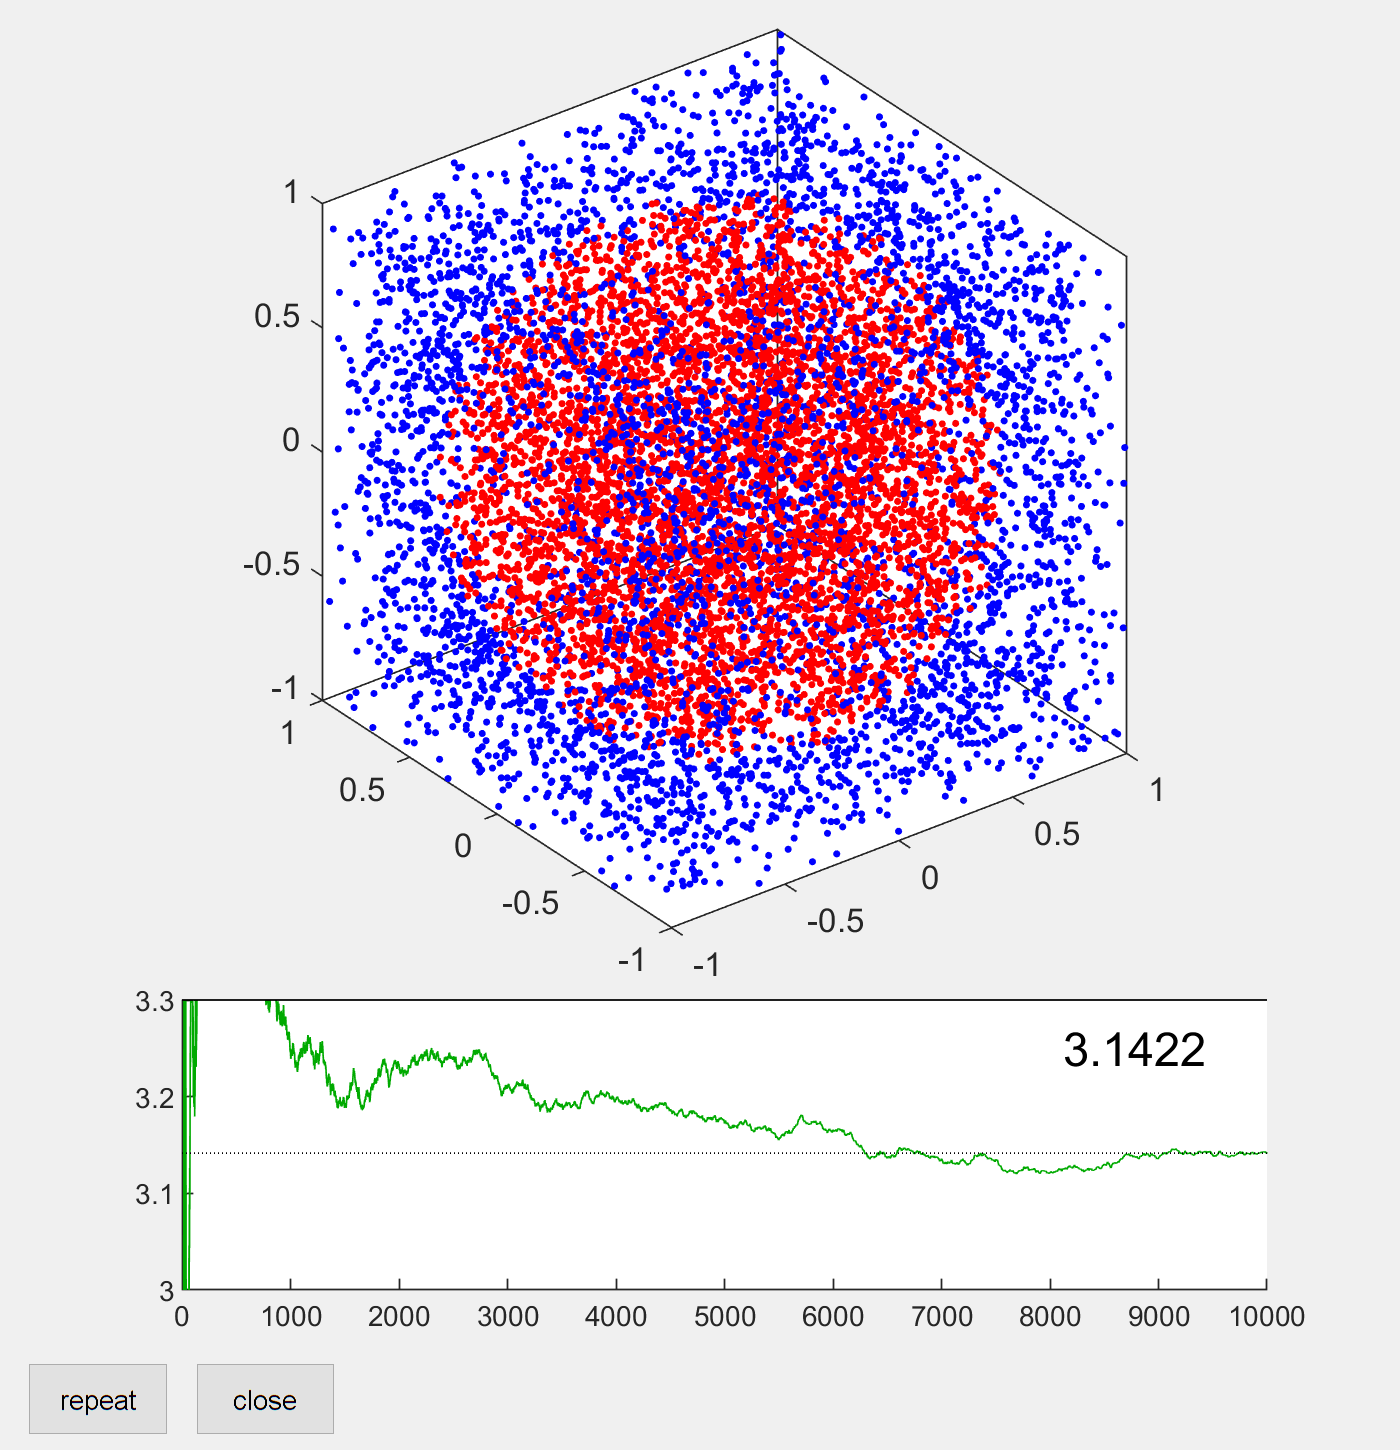

randgui(['rand'])

## Example: Decay of An Isotope

- The radioisotope thallium-208 decays to a stable lead-208 atom with a half-life of 3.053 minutes

- The *average *number of particles left is 


$$N(t) = N_0 (2^{-t/t_{1/2}})$$


- The probability that any *one* thallium has decay is 


$$p(t) = 1 - \frac{N(t)}{N(0)} = 1 -2^{-t/t_{1/2}}$$


this is the probability that a single atom decays in time *t*

*Look at *`isotopedecay.m` and` isotopedecay2.m `(Thallium Decay Problem)

- `isotopedecay.m` produces a series of random numbers that are compared to the probability of decay at time *t* and then used to calculate the amount of thallium left

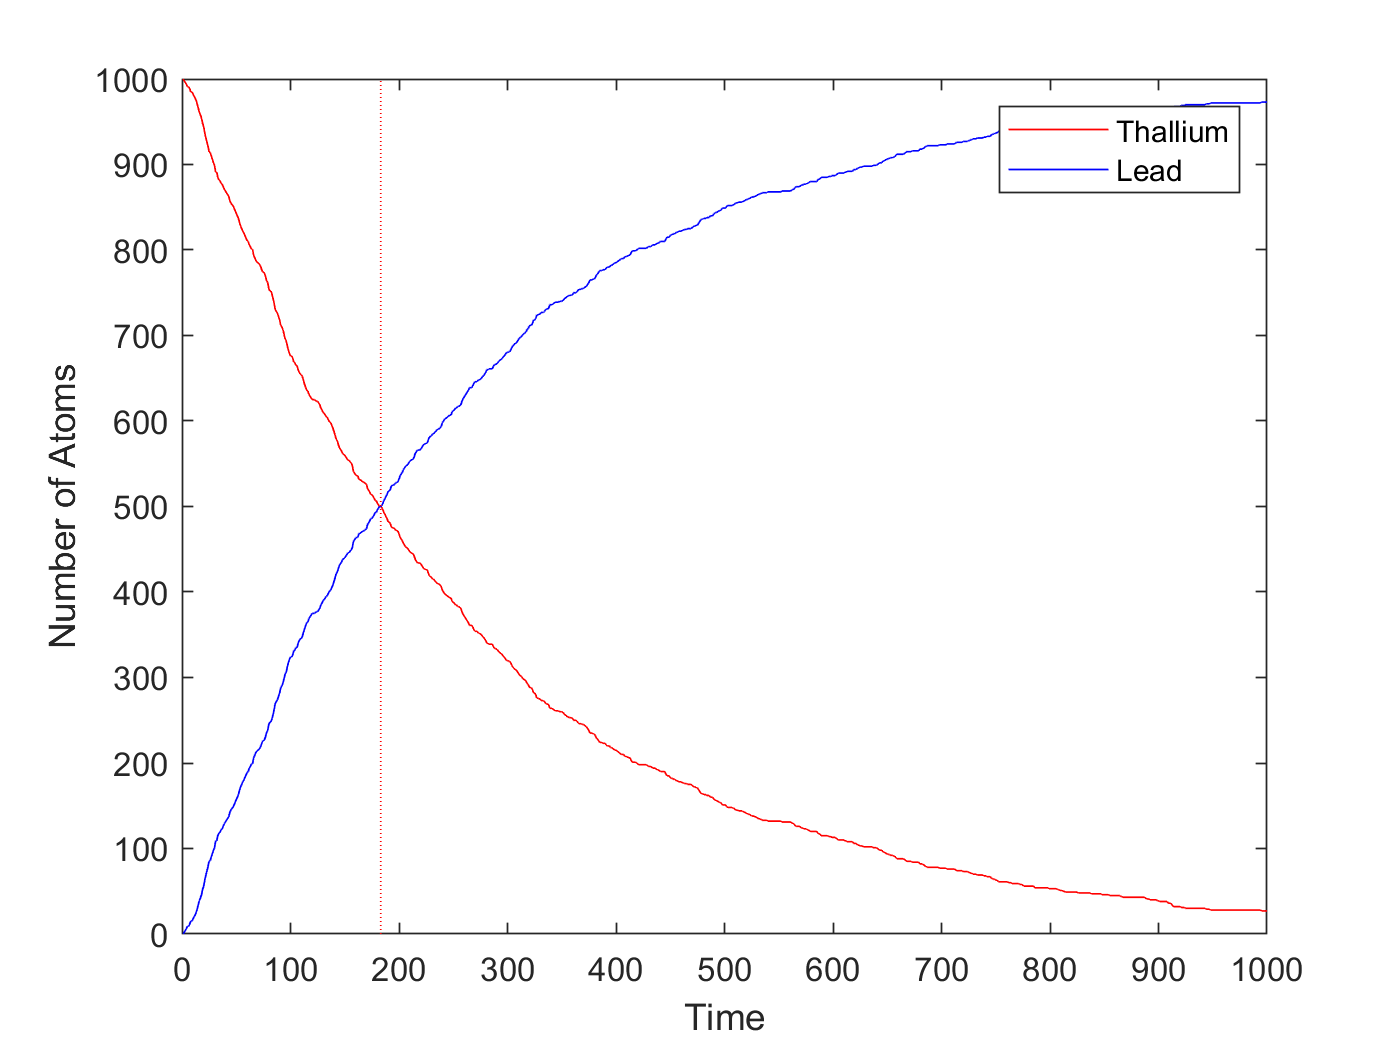

isotopedecay

## Non-Uniform Random Numbers

- The probability the a particle decays in time *t* is 


$$1-2^{-t/t_{1/2}}$$


- The probability that it decays in a small time period *dt*


$$1-2^{dt/t_{1/2}} = 1-exp\left[\frac{t}{t_{1/2}ln(2)}\right] \approx \frac{dt}{\tau}$$


What is the probability of decay in between the times *t *and *t+dt*?

- The particle has to not decay up to *t*, 


$$P(t) = e^{-t/\tau}$$


- Then during the next *dt**, *


$$P(dt) = \frac{dt}{\tau}$$


- The total probability is then


$$P(t) = e^{-t/\tau}\left(\frac{dt}{\tau}\right)$$


Therefore a “better program” would have drawn from an exponential distribution to represent the times at which a particle decayed (see `isotopedecay2.m`)

## `RAND`

`rand` produces random numbers from a uniform distribution between 0 and 1

- produces an n x n matrix of random numbers

- produces a n x m x ___ matrix of random numbers

- 'type' specifies the numeric type returned by the function

`double / single`

- can also use p as a model for the numeric type returned

r1 = rand

r1 =    0.917942868205920

r2 = rand(5)

r2 =    0.276559417714024   0.365378371143920   0.822537855120205   0.201452236326331   0.110787919033807
   0.461018064705375   0.345420641990836   0.760233398614179   0.612266236814180   0.282615582188235
   0.087964925419506   0.887663570195459   0.426498890462774   0.176830394088963   0.378717025156219
   0.873248261367504   0.977917636280491   0.979365582731385   0.944217498851857   0.488667900349650
   0.265770251287355   0.635738935965810   0.318869888132546   0.163356513196815   0.251188112675759


r3 = rand([2,6])

r3 =    0.384876217261485   0.049975974230132   0.551113681947509   0.238754862465754   0.651856623595579   0.390554852149117
   0.953571572820438   0.115437733154767   0.960007876949376   0.937222769146290   0.966237442615398   0.041533334091175


x = single(34);
r4 = rand(3,'like',x)

r4 = 3×3 single matrix
   0.1994542   0.8276942   0.0656086
   0.4850251   0.4607892   0.4708089
   0.5034321   0.1749816   0.6560692


rand([5000 1])

ans =    0.781464076330384
   0.208711759256397
   0.911445542061496
   0.392044640266258
   0.477959920264358
   0.821457627278938
   0.138667934280311
   0.031965787349578
   0.980737786833231
   0.136386891499500


## RANDI

`randi `returns a random** integer**

- returns random numbers between `imin` an `imax`

- returns an `n1` x `n2` x … matrix of random number

- can specify the return type (`'int8', 'int16', 'int32'`,...) with classname or an example number *p*

ri = randi(20)

ri =     10

rm = randi(20,[4 4])

rm =      7    15     8    15
     7    10     4    13
    19    15     1     6
     8     4     4     8


rmr = randi([3 15],[2 2])

rmr =      5     4
     3     6


rmt = randi([4 10],2,'int8')

rmt = 2×2 int8 matrix
   5   6
   7   9


## RANDN

`randn` returns a normally distributed number

- can return an *n x n *matrix or a *n1 x **nN* matrix

- can specify the return type (`'int8', 'int16', 'int32'`,...) with `classname` or an example number p

randn(4)

ans =    0.244302115066350  -0.302797605410107   1.162358977221953  -2.304466612938218
  -0.508250797732938  -0.165920776400670   0.007975182212288   0.175380701643771
  -0.347566412398579  -0.585946704641931   0.481040490661959  -1.586490540699482
   0.987909646025795   0.260785913753523   0.762300309011308  -1.849399809429134


randn(4,1)

ans =    0.073727385900797
   0.388854344351080
   1.028101344365013
   0.233824727494327


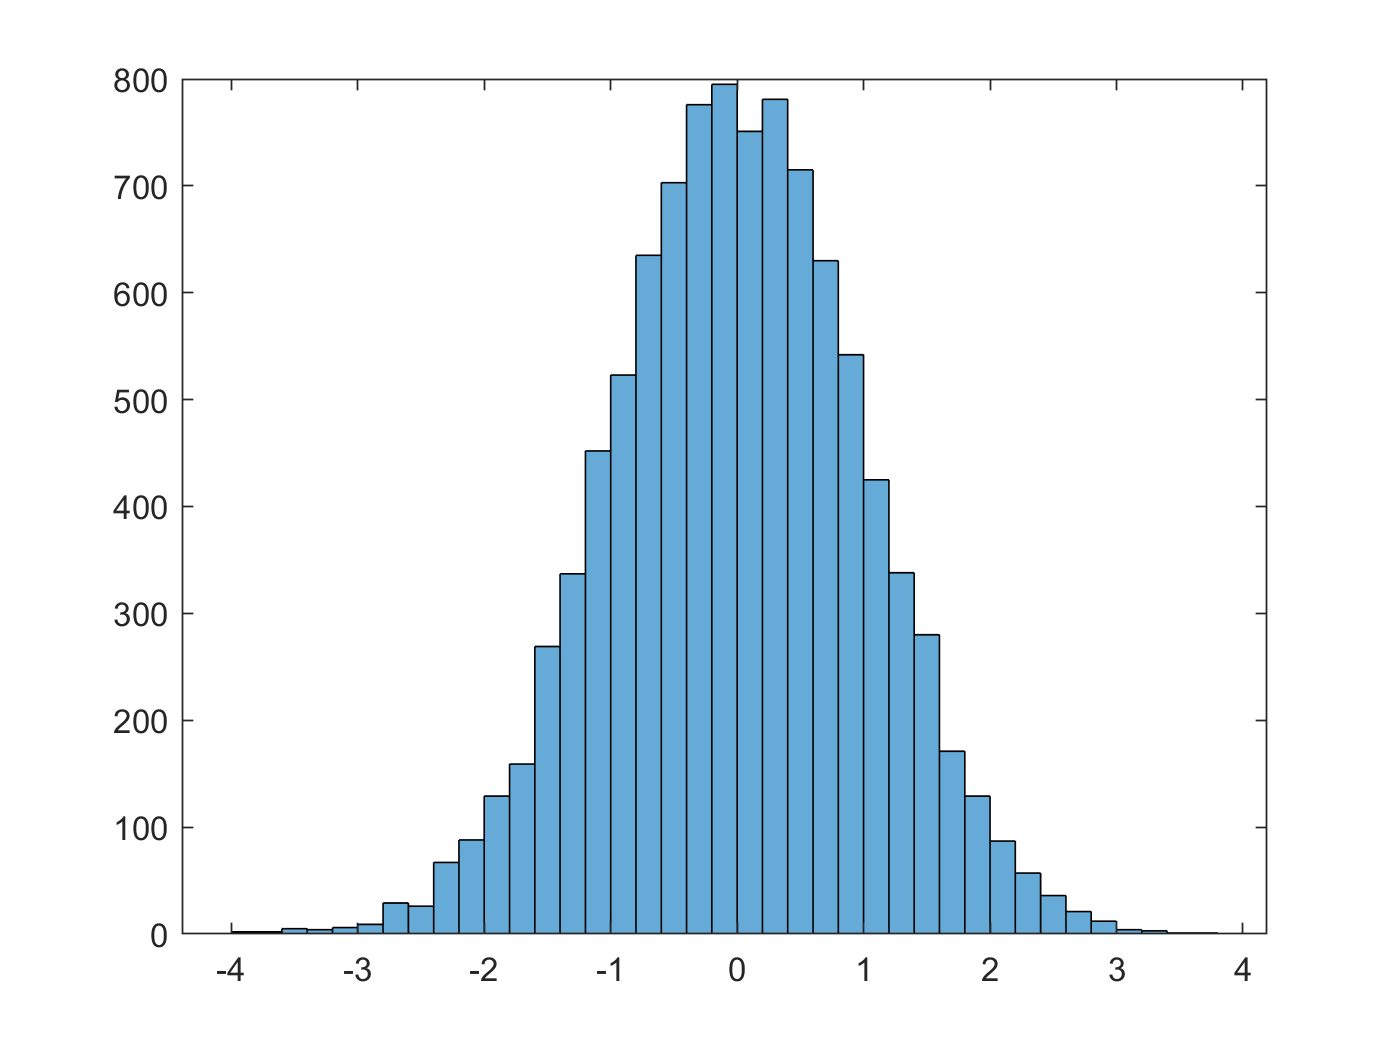

histogram(randn(10000,1))

## RANDOM

Returns a random number taken from a probability distribution (*more on this later*)

- Make a probability distribution by 

- `distname` is a char array with the distribution’s name: `‘Gamma’ `or `‘Normal’`

- `‘name’` is also a name of the probability distribution – use this to skip creating a pd explicitly

pdgamma = makedist('gamma','a',2,'b',2)
pdgamma2 = makedist('gamma','a',3,'b',15)
g=random(pdgamma,100);
g2 = random(pdgamma2,100);
histogram(g)
hold on
histogram(g2)
hold off